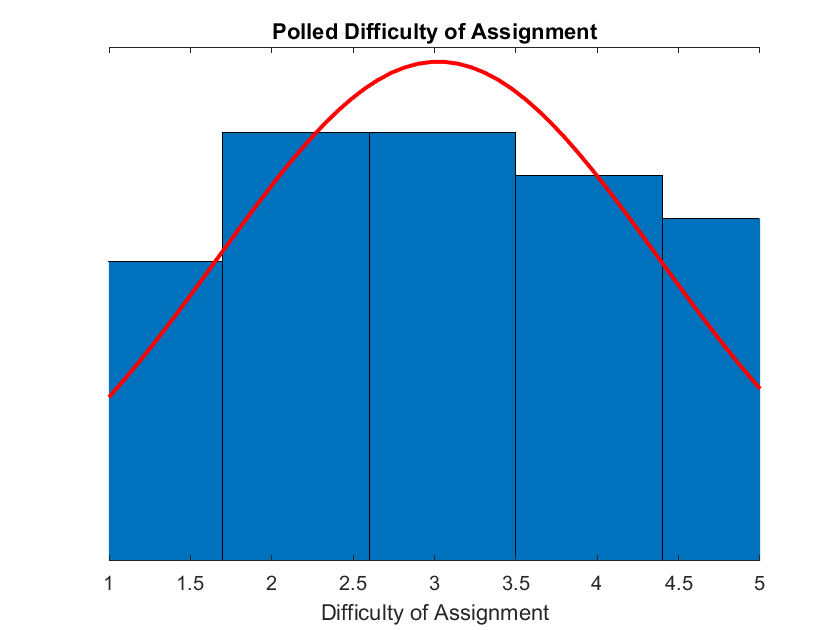

% from https://www.mathworks.com/matlabcentral/fileexchange/39915-getgooglespreadsheet
% need to convert string to number
    % str2double(str) to make a number

key = '1nvt2f8dS1jChkmXYDk4i6ajvOROoZzXj4u9sgRaq4Fk';

% importing spreadsheet
res = str2double(GetGoogleSpreadsheet(key));

difficulty = res(2:end, 4);

% dificulty_med = median(difficulty);
% 
% per_ass_done = res( 2:end , 2);
% time_taken = res( 2:end , 3);

% Scatter Plot
% plot(time_taken, per_ass_done, 'b.', 'MarkerSize', 10)
% ylim([0 100])
% ylabel("Percentage to Assignment Done (%)" )
% xlabel("Time Taken (hours)")
% title("Scatter Plot Percentage of Assignment Done vs. Time Taken")

f1 = figure;
histfit(difficulty, 5, "Normal")
xlim([1 5])
ax1 = gca;                   % gca = get current axis
ax1.YAxis.Visible = 'off';   % remove y-axis
ax1.XAxis.Visible = 'on';   % keep x-axis
xlabel("Difficulty of Assignment")
title("Polled Difficulty of Assignment")

Error using evalmxdom>instrumentAndRun (line 116)
Publishing a script that contains a publish function is not supported.

Error in evalmxdom (line 21)
[data,text,laste] = instrumentAndRun(file,cellBoundaries,imageDir,imagePrefix,options);

Error in publish


% shows code in HTML but not the output
publish('newhacks.mlx');

% web('html/newhacks.html');

% normpdf(difficulty)
% plot(difficulty, normpdf(difficulty))

% bar(difficulty)
% hold on
% difficulty_curve = normpdf(difficulty)
% plot(difficulty, difficulty_curve, 'LineWidth', 10)
% hold off
% axis padded

% bell curve
% denom_bell_difficulty = std(difficulty) * sqrt(2 * pi)
% exp_bell_difficulty = -1/2 * (difficulty - mean(difficulty))/std(difficulty)^2
% bell_difficulty = 1 / denom_bell_difficulty * exp(1) .^ exp_bell_difficulty
% plot(difficulty, bell_difficulty) % gives straight line

